cd('/gpfs/fs1/home/aanand6/Documents/MATLAB/psyche');
theta45=asin(sqrt(2)/sqrt(3))*180/pi;
fsim_thetas=[90, 46,  8,  46,  90, 134,172,134];
fsim_phis=  [-8,-11,-90,-169,-172,-169,-90,-11];
                                        % top edge(2), corner(4), back(1), side edge(2)
sim_thetas=[90, 45.55492003,  8, 45.55492003,  90,   134.44508,172,134.44508];
sim_phis=  [-8,-11.24131289,-90,-168.7586871,-172,-168.7586871,-90,-11.24131289];

% Array which says face=2, edge=4, corner=8 [Cases] - Obsolete
og_c = 8;       % Original cases
fnl = "f"+round(fsim_thetas(1:og_c))+"_"+round(fsim_phis(1:og_c))+".txt";
% NOTE: File starting with just f have the position already in the asteroid
% coordinates and do not need to be transformed.
fn = length(sim_phis);
fbv = "v4_"+round(fsim_thetas(1:og_c))+"_"+round(fsim_phis(1:og_c))+"_2.5R";

cases = ones(length(fsim_phis),1);
CT = sum(cases);

% 90	        -8
% 45.55492003	-11.24131289
% 8	            -90
% 45.55492003	-168.7586871
% 90	        -172
% 134.44508	    -168.7586871
% 172	        -90
% 134.44508	    -11.24131289

unit_vec = zeros(CT,3);
cc = 1; 

for ii=1:fn
    unit_vec(cc,:) = [sind(sim_thetas(ii))*cosd(sim_phis(ii)), sind(sim_thetas(ii))*sind(sim_phis(ii)), ...
            cosd(sim_thetas(ii))];
    for jj=2:cases(ii)
        unit_vec(cc+jj-1,:) = sim_transformations{ii}{jj}*unit_vec(cc,:)';
    end
    cc=cc+cases(ii);
end
size(unique(unit_vec, 'rows'))

ans =      8     3


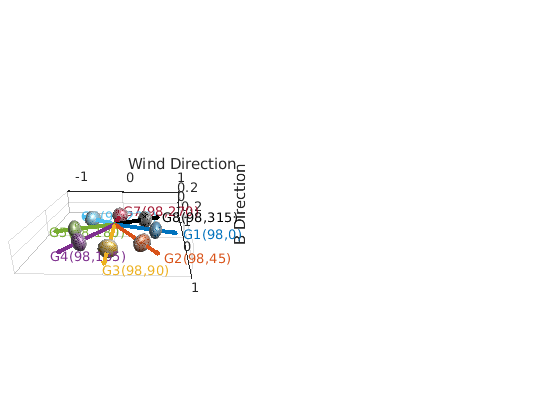

d_vec = zeros(CT,3);
lv=d_vec;
colors = lines(CT);
colors(8,:) = [0, 0, 0];
lbl = "P"+linspace(1,CT,CT)'+"("+round(98)+","+round([0:7]*45)'+")";

figure,
for ii=1:CT
    d_vec(ii,:) = [sind(sim_thetas(ii))*cosd(sim_phis(ii)), sind(sim_thetas(ii))*sind(sim_phis(ii)), ...
            cosd(sim_thetas(ii))];
    for jj=1:3
        if d_vec(ii,jj)~=0
            lv(ii,jj)=d_vec(ii,jj); %/d_vec(ii,jj);
        end
    end
%     plot3([0,lv(ii,1)],[0,lv(ii,2)],[0,lv(ii,3)],'color',colors(ii,:),'DisplayName',...
%         strcat(char(64+ii),'(',num2str(lv(ii,1)),',',num2str(lv(ii,2)),',',num2str(lv(ii,3)),')'),...
%         'LineWidth',3);
    quiver3(0,0,0,lv(ii,1),lv(ii,2),lv(ii,3),'color',colors(ii,:),'DisplayName',...
        strcat(char(64+ii),'(',num2str(lv(ii,1)),',',num2str(lv(ii,2)),',',num2str(lv(ii,3)),')'),...
        'LineWidth',3);
    if ii==1
        hold on;
%         set(gca,'yminortick','off');
    end
    text(lv(ii,1),lv(ii,2),lv(ii,3),lbl(ii),'color',colors(ii,:));
    [x,y,z] = ellipsoid(0,0,0,0.125,0.125,0.085); % with centre at the origin
    x=-x;
    y=-y;
    xyz = rotz(sim_phis(ii))*roty(sim_thetas(ii))*[x(:),y(:),z(:)]'; % rotate the ellipsoid coordinate
    xp = reshape(xyz(1,:), size(x)) +lv(ii,1)*0.6; % recover the coordinate of x-component
    yp = reshape(xyz(2,:), size(y)) +lv(ii,2)*0.6; % recover the coordinate of y-component
    zp = reshape(xyz(3,:), size(z)) +lv(ii,3)*0.6; % recover the coordinate of z-component
    gm=mesh(xp,yp,zp,'facecolor',colors(ii,:),'edgecolor','w','EdgeAlpha',0.5,'facealpha',1); % mesh the rotated ellipsoid
    gm.FaceLighting="gouraud";
end
legend('hide','Location', 'Best');
text(0.2,0.95,1,'$\longrightarrow$','Interpreter','latex');
text(0.97,0.45,1.15,'$\uparrow$','Interpreter','latex');
hold off;
axis equal
grid('on');
xlabel('Wind Direction'); ylabel('B Direction');
set(gca,'CameraPosition',[.6 1.5 3.6],'CameraTarget',[0.5 0.5 0.5],...
    'CameraViewAngle',45,'DataAspectRatio',[1 1 1],'Projection','perspective','CameraUpVector',[0 1 0]);
xlim([-1 1]); ylim([-0.2 0.2]); zlim([-1 1]);
camlight;

R = 125;
n = 101;
a_e = [125; 125*0.9];
b_e = [85; 85*0.9];
% Volume of the cells turns out to be ~1.5e6 km^3 = 1.5e15m^3

% [X,Y,Z] = sphere(n);
th = linspace(0,pi,n);
phi = linspace(0,2*pi,n);
rs = linspace(R-10,R,2);

[rr,tt,pp] = ndgrid(rs,th,phi);
for ii =1:length(rs)
    rr(ii,:,:)=1./sqrt((sin(tt(ii,:,:)).*cos(pp(ii,:,:))./a_e(ii)).^2+ ...
        (sin(tt(ii,:,:)).*sin(pp(ii,:,:))./a_e(ii)).^2+(cos(tt(ii,:,:))./b_e(ii)).^2);
end

rsc=0.25*(rs(2:end).^4-rs(1:end-1).^4)./((1.0/3.0)*(rs(2:end).^3-rs(1:end-1).^3));
phic=0.5*(phi(1:end-1)+phi(2:end));
thc=acos(0.5*(cos(th(1:end-1))+cos(th(2:end))));

[rrc,ttc,ppc] = ndgrid(rsc,thc,phic);
vc=(-1/3)*((0.5*(rr(2:end,1:end-1,1:end-1)+rr(2:end,2:end,1:end-1))).^3-(0.5*(rr(1:end-1,1:end-1,1:end-1)...
    +rr(1:end-1,2:end,1:end-1))).^3).*(cos(tt(1:end-1,2:end,1:end-1))-cos(tt(1:end-1,1:end-1,1:end-1))).* ...
    (pp(1:end-1,1:end-1,2:end)-pp(1:end-1,1:end-1,1:end-1));    % Volume of cells, Take avg of inner and outer radii.
volc=vc;
for ii = 1:length(rs)-1
    for jj = 1:length(thc)
        for kk = 1:length(ppc)
            % Currently the radius line only works for azimuthally symmeteric ellipse (a=b/=c)
            rrt1 = 1./sqrt((sin(ttc(ii,jj,kk))./a_e(1)).^2+(cos(ttc(ii,jj,kk))./b_e(1)).^2);
            rrt2 = 1./sqrt((sin(ttc(ii,jj,kk))./a_e(2)).^2+(cos(ttc(ii,jj,kk))./b_e(2)).^2);
            rrc(ii,jj,kk)=0.25*(rrt2.^4-rrt1.^4)./((1.0/3.0)*(rrt2.^3-rrt1.^3));
%             rrc(ii,jj,kk)=0.25*(rr(ii+1,jj+1,kk+1).^4-rr(ii,jj,kk).^4)./ ...
%                 ((1.0/3.0)*(rr(ii+1,jj+1,kk+1).^3-rr(ii,jj,kk).^3));
           volc(ii,jj,kk) = (-1/3)*(rrt1.^3-rrt2.^3).*(cos(tt(ii,jj+1,kk))-cos(tt(ii,jj,kk))).* ...
                            (pp(ii,jj,kk+1)-pp(ii,jj,kk));
        end
    end
end
xxc=rrc.*sin(ttc).*cos(ppc);
yyc=rrc.*sin(ttc).*sin(ppc);
zzc=rrc.*cos(ttc);

% for aa=1:4:fn
%     A = load(fnl(aa));
%     pos = A(:,1:3);             % Postition of dipole's center
%     m = A(:,4:6);               % Magnetic field at dipole
%     % We are currently excluding the normalization to the dipole moment of each
%     % dipole element/cell
%     theta_=sim_thetas(aa); 
%     phi_=sim_phis(aa); 
% 
%     pos_r = roty(-theta_)*rotz(-phi_)*pos'; 
%     % ***Insert cases here for different m_r***
%     m_r_1 = rotz(-phi_)*roty(-theta_)*m';     % for Ry make m_r -ve
%     sum(m,1)
%     sum(m_r_1',1)
%     sum(abs(pos_r'),1)
% end

cc=1;
MMC = zeros(CT,numel(xxc),3);
dM = zeros(CT,3);
dMcy = zeros(CT,3);
Qn = zeros(CT,2);
dQ = zeros(CT,6); % xx,yy,zz,xy,yz,zx
dMM = zeros(CT,9);

mu_0 = 4e-7*pi;
chiSI = 1e6*1e-9;      % Taking log chi=6. Higher than that of available data.
rhoSI = 4e3;    % Density of Psyche
chiM = chiSI*rhoSI;
cellD = 3000/48/2^4; % in km
AB_T = 4.165304713778593e-12;
%Magnetic field scale.data in AstroBEAR takes it to gauss (= 1e-4 T)
cSI = (chiM)*AB_T*1e9/mu_0;
% 1e9 for volume km^3 to m^3

for aa=1:fn
    A = load(fnl(aa));
    pos = A(:,1:3);             % Postition of dipole's center
    m = A(:,4:6);               % Magnetic field at dipole
    % We are currently excluding the normalization to the dipole moment of each
    % dipole element/cell
    theta_=sim_thetas(aa); 
    phi_=sim_phis(aa); 

    % % pos_r = roty(-theta_)*rotz(-phi_)*pos'; 
    % Fortran now exports in the frame of the asteroid.
    pos_r = pos';
    % ***Insert cases here for different m_r***
    m_r_1 = roty(-theta_)*rotz(-phi_)*m';     % for Ry make m_r -ve
    
    for jj=1:cases(aa)
        m_r = m_r_1;
        F1 = scatteredInterpolant(pos_r',m_r(1,:)','linear','nearest');
        F2 = scatteredInterpolant(pos_r',m_r(2,:)','linear','nearest');
        F3 = scatteredInterpolant(pos_r',m_r(3,:)','linear','nearest');
        mx = reshape(F1(xxc(:),yyc(:),zzc(:)),size(xxc));
        my = reshape(F2(xxc(:),yyc(:),zzc(:)),size(xxc));
        mz = reshape(F3(xxc(:),yyc(:),zzc(:)),size(xxc));
        
        m_sph=zeros(numel(mx),3);
        for ii=1:numel(mx)
            m_sph(ii,:) = cart2sphvec([mx(ii);my(ii);mz(ii)],atan2d(yyc(ii),xxc(ii)),...
                asind(zzc(ii)/rrc(ii)));
        end
        
        %% Averaging (How to handle arbitrary spin? Weights?)
        % Azimuthal averaging - average over phi
        nt=n-1; np=n-1;
        tmp = 0;
        m_sphr = reshape(m_sph(:,3),size(xxc));
        m_sphth = reshape(m_sph(:,2),size(xxc));    % *The th=pi/2-el does not matter as its immediately converted back
        m_sphp = reshape(m_sph(:,1),size(xxc));
        
        mra = repmat(mean(m_sphr,3),[1,1,size(m_sphr,3)]);
        % mra = m_sphr, try mean along 2nd dim, [1, size(m_sphr,2), 1]
        mtha = repmat(mean(m_sphth,3),[1,1,size(m_sphth,3)]);
        mpa = repmat(mean(m_sphp,3),[1,1,size(m_sphp,3)]);
        
        m_c=zeros(numel(mx),3);
        for ii=1:numel(mx)
        %     m_c(ii,:) = sph2cartvec([m_sph(ii,1);m_sph(ii,2);m_sph(ii,3)],atan2d(yyc(ii),xxc(ii)),...
        %         asind(zzc(ii)/rrc(ii)));
            m_c(ii,:) = sph2cartvec([mpa(ii);mtha(ii);mra(ii)],atan2d(yyc(ii),xxc(ii)),...
                asind(zzc(ii)/rrc(ii)));
        end
        
        MMC(cc,:,:) = m_c;

% To plot the field around all the cases
%         if aa>og_c
%             continue;
%         end
%         if ~ismember(cc,pm)
%             continue;
%         end

        % *** Find Dipole moment by integration ***
        dM(cc,1:3) = sum(volc(:).*m_c(:,1:3));
        dMcy(cc,1) = cSI*sum(volc(:).*(m_c(:,1).*xxc(:)+yyc(:).*m_c(:,2))./(sqrt(xxc(:).^2+yyc(:).^2)));
        dMcy(cc,2) = cSI*sum(volc(:).*(m_c(:,2).*xxc(:)-yyc(:).*m_c(:,1))./(sqrt(xxc(:).^2+yyc(:).^2)));
        % Project individual 
  
        % *** Find Quaropole moment by integration *** % xx,yy,zz,xy,yz,zx
%         dQ(cc,1:3) = sum(2*volc(:).*prod(m_c(:,1:3),[xxc(:),yyc(:),zzc(:)],2));
        dQ(cc,1) = sum(2*volc(:).*m_c(:,1).*xxc(:));
        dQ(cc,2) = sum(2*volc(:).*m_c(:,2).*yyc(:));
        dQ(cc,3) = sum(2*volc(:).*m_c(:,3).*zzc(:));
        dQ(cc,4) = sum(volc(:).*(m_c(:,2).*xxc(:)+yyc(:).*m_c(:,1)));
        dQ(cc,5) = sum(volc(:).*(m_c(:,2).*zzc(:)+yyc(:).*m_c(:,3)));
        dQ(cc,6) = sum(volc(:).*(m_c(:,1).*zzc(:)+xxc(:).*m_c(:,3)));
        tr_t = sum(dQ(cc,1:3));
        % Multipy by km/m.

        dMM(cc,:) = cSI*[dM(cc,1:3),(3*dQ(cc,1:3)-tr_t),dQ(cc,4:6)];
        Qn(cc,:) = [sqrt(3/(4*pi))*dMM(cc,3),0.5*sqrt(5/(4*pi))*dMM(cc,6)];
        dMcy(cc,3) = dMM(cc,3);

%         %% Define the grid
%         npoints=201;
%         xx1=linspace(-2.5*R,2.5*R,npoints);
%         yy1=[xx1(1)-xx1(2),0,xx1(2)-xx1(1)];
%         zz1=xx1;
%         sz=length(xx1);
%         [X,Y,Z]=ndgrid(xx1,yy1,zz1);
% %         mask=((X/(1.1*a_e(1))).^2+(Y/(1.1*a_e(1))).^2+(Z/(1.1*b_e(1))).^2)<1;     % dr=5km
% %         X(mask)=[];
% %         Y(mask)=[];
% %         Z(mask)=[];
%         pos_mesh = cat(2,X(:),Y(:),Z(:))';
%         pos_rc = cat(2,xxc(:),yyc(:),zzc(:))';
% 
%         bd1d=zeros(size(pos_mesh));
%         for i=1:size(pos_rc,2) % Loop over dipoles
%             r=pos_mesh-pos_rc(:,i);   
%             rm=sum(r.^2,1).^(1/2);
%             bd1d=bd1d+(3*r.*sum(m_c(i,:)'.*r,1)./rm.^5-m_c(i,:)'./rm.^3).*volc(i);    
%         end
%         % bd1d(:,mask)=0;
%         bd1d=AB_T*(chiM)*bd1d*1e9/(4*pi); % convert to nT 
%         % (left the rm conversion in mu_0/4pi in the previous version)
%         % 1e9 from volume cancel out 1e9 from r^-3. 
%         % mu_0 cancels out --> not using bulk conversion (mSI) so m=B_r*V/mu_0
%         % cSI = (chiM)*AB_T*1e9/mu_0;
%         writebov3dvector(fbv(cc),min(pos_mesh,[],2), max(pos_mesh,[],2), 0, reshape(bd1d.', ...
%             [sz,length(yy1),sz,3]), 'B');

        cc=cc+1;
    end
end

rto = (sqrt(sum(dQ(:,1:3)'.^2))./dM(:,3)')';
%print('Moment');

stride=2;
th_norm = max(sin(thc(:)))^2;
ntry=0;
for jj=1:stride:n-1
    phi_n = (n-1)*sin(thc(jj))/stride/th_norm;
    for kk=round(linspace(1,100,ceil(phi_n)))
        ntry=ntry+1;
    end
end

for ii=1:CT
    m_ce = MMC(ii,:,:);
    m_c = reshape(m_ce,size(m_c));
    m_SI = volc(:).*m_c*cSI;
    fokc = "mSI_"+round(fsim_thetas(ii))+"_"+round(fsim_phis(ii))+".okc";
    fileID = fopen(fokc,'w');
    % disp(og_cases(ii))
    fprintf(fileID,'%d %d %d\n',6,ntry,6);
    fprintf(fileID,'x\ny\nz\nBx\nBy\nBz\n');
    for jj=1:3
        fprintf(fileID,'%g %g %d\n',1.1*min(xxc(:)),1.1*max(xxc(:)),8);
    end
    for jj=1:3
        fprintf(fileID,'%g %g %d\n',1.1*min(m_SI(:)),1.1*max(m_SI(:)),8);
    end
    for jj=1:stride:n-1
        phi_n = (n-1)*sin(thc(jj)).^2/stride/th_norm;
        for kk=round(linspace(1,100,ceil(phi_n)))
            aa=(n-1)*(kk-1)+jj;     % In 3D array, 2nd index is column?
            fprintf(fileID,'%g %g %g %g %g %g\n',xxc(aa),yyc(aa),zzc(aa),m_SI(aa,1),m_SI(aa,2),m_SI(aa,3));
        end
    end
    fclose(fileID);
end

% for ii=1:length(poloidal)
%     m_ce = MMC(poloidal(ii),:,:);
%     m_c = reshape(m_ce,size(m_c));
%     npoints=201;
%     xx1=linspace(-2.5*R,2.5*R,npoints);
%     yy1=[xx1(1)-xx1(2),0,xx1(2)-xx1(1)];
%     zz1=xx1;
%     sz=length(xx1);
%     [X,Y,Z]=ndgrid(xx1,yy1,zz1);
%     pos_mesh = cat(2,X(:),Y(:),Z(:))';
%     pos_rc = cat(2,xxc(:),yyc(:),zzc(:))';
% 
%     bd1d=zeros(size(pos_mesh));
%     for i=1:size(pos_rc,2) % Loop over dipoles
%         r=pos_mesh-pos_rc(:,i);   
%         rm=sum(r.^2,1).^(1/2);
%         bd1d=bd1d+(3*r.*sum(m_c(i,:)'.*r,1)./rm.^5-m_c(i,:)'./rm.^3).*volc(i);    
%     end
% %         bd1d(:,mask)=0;
%     writebov3dvector(strcat(num2str(poloidal(ii)),'_e125_2.5R'),min(pos_mesh,[],2), max(pos_mesh,[],2), 0, reshape(bd1d.', ...
%         [sz,length(yy1),sz,3]), 'B');
% end

m_ce = 0*MMC(1,:,:);
for ii=1:CT
    m_ce = m_ce+MMC(ii,:,:);
end

%% NOTE THE NORMALIZATION TO SI
m_c = cSI*reshape(m_ce/CT,size(m_c));
% *** Find Dipole moment by integration ***
dMA(1:3) = sum(volc(:).*m_c(:,1:3));
dMcyA = dMA;
dMcyA(1) = sum(volc(:).*(m_c(:,1).*xxc(:)+yyc(:).*m_c(:,2))./(sqrt(xxc(:).^2+yyc(:).^2)));
dMcyA(2) = sum(volc(:).*(m_c(:,2).*xxc(:)-yyc(:).*m_c(:,1))./(sqrt(xxc(:).^2+yyc(:).^2)));

dQA= zeros(1,6);
% *** Find Quaropole moment by integration *** % xx,yy,zz,xy,yz,zx
%         dQ(cc,1:3) = sum(2*volc(:).*prod(m_c(:,1:3),[xxc(:),yyc(:),zzc(:)],2));
dQA(1) = sum(2*volc(:).*m_c(:,1).*xxc(:));
dQA(2) = sum(2*volc(:).*m_c(:,2).*yyc(:));
dQA(3) = sum(2*volc(:).*m_c(:,3).*zzc(:));
dQA(4) = sum(volc(:).*(m_c(:,2).*xxc(:)+yyc(:).*m_c(:,1)));
dQA(5) = sum(volc(:).*(m_c(:,2).*zzc(:)+yyc(:).*m_c(:,3)));
dQA(6) = sum(volc(:).*(m_c(:,1).*zzc(:)+xxc(:).*m_c(:,3)));
tr_t = sum(dQA(1:3));

dMMA = [dMA(1:3),(3*dQA(1:3)-tr_t),dQA(4:6)];
QnA = [sqrt(3/(4*pi))*dMMA(3),0.5*sqrt(5/(4*pi))*dMMA(6)];

stride=2;
th_norm = max(sin(thc(:)))^2;
ntry=0;
for jj=1:stride:n-1
    phi_n = (n-1)*sin(thc(jj))/stride/th_norm;
    for kk=round(linspace(1,100,ceil(phi_n)))
        ntry=ntry+1;
    end
end

m_SI = volc(:).*m_c;
fokc = "mSI_rev"+".okc";
fileID = fopen(fokc,'w');
% disp(og_cases(ii))
fprintf(fileID,'%d %d %d\n',6,ntry,6);
fprintf(fileID,'x\ny\nz\nBx\nBy\nBz\n');
for jj=1:3
    fprintf(fileID,'%g %g %d\n',1.1*min(xxc(:)),1.1*max(xxc(:)),8);
end
for jj=1:3
    fprintf(fileID,'%g %g %d\n',1.1*min(m_SI(:)),1.1*max(m_SI(:)),8);
end
for jj=1:stride:n-1
    phi_n = (n-1)*sin(thc(jj)).^2/stride/th_norm;
    for kk=round(linspace(1,100,ceil(phi_n)))
        aa=(n-1)*(kk-1)+jj;     % In 3D array, 2nd index is column?
        fprintf(fileID,'%g %g %g %g %g %g\n',xxc(aa),yyc(aa),zzc(aa),m_SI(aa,1),m_SI(aa,2),m_SI(aa,3));
    end
end
fclose(fileID);

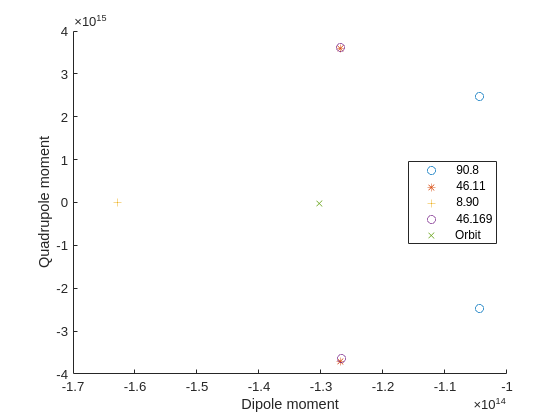

figure,
scatter(Qn(1:4:end,1),Qn(1:4:end,2),'DisplayName',fnl{1}(2:end-4))
hold on
scatter(Qn(2:4:end,1),Qn(2:4:end,2),'*','DisplayName',fnl{2}(2:end-4))
scatter(Qn(3:4:end,1),Qn(3:4:end,2),'+','DisplayName',fnl{3}(2:end-4))
scatter(Qn(4:4:end,1),Qn(4:4:end,2),'DisplayName',fnl{4}(2:end-4))
scatter(QnA(:,1),QnA(:,2),'x','DisplayName','Orbit')
legend('show','Location','best');
xlabel('Dipole moment'); ylabel('Quadrupole moment')

%% Define the grid
npoints=501;
xx1=linspace(-2.5*R,2.5*R,npoints);
yy1=[xx1(1)-xx1(2),0,xx1(2)-xx1(1)];
zz1=xx1;
sz=length(xx1);
[X,Y,Z]=ndgrid(xx1,yy1,zz1);
%b=zeros(sz,sz,sz,3);  
mask=(X.^2+Y.^2+Z.^2)<(R+10)^2;     % dr=5km
pos_mesh = cat(2,X(:),Y(:),Z(:))';
pos_rc = cat(2,xxc(:),yyc(:),zzc(:))';

bd1d=zeros(size(pos_mesh));
for i=1:size(pos_rc,2) % Loop over dipoles
    r=pos_mesh-pos_rc(:,i);   
    rm=sum(r.^2,1).^(1/2);
    bd1d=bd1d+(3*r.*sum(m_c(i,:)'.*r,1)./rm.^5-m_c(i,:)'./rm.^3).*volc(i);    
end
% bd1d(:,mask)=0;
bd1d=1e9*1e-9*1e-7*bd1d; % convert to nT (left the 1e-7 from mu_0/4pi, volume)
% Take vector moments
% b = k*b;

## BOV File

%%
writebov3dvector('revSI_2.5R',min(pos_mesh,[],2), max(pos_mesh,[],2), 0, ...
    reshape(bd1d.',[sz,length(yy1),sz,3]), 'B');

function writebov3dvector(name, lower, upper, tnow, data, varname)
    f=fopen(name+".bov",'w');
    datafile=name+".dat";
    fprintf(f, 'TIME: %f\n', tnow);
    fprintf(f, 'DATA_FILE: %s\n', datafile);
    fprintf(f, 'DATA_SIZE: %d %d %d\n', size(data,1), size(data, 2), size(data,3));
    fprintf(f, 'DATA_FORMAT: DOUBLE\n');
    fprintf(f, 'VARIABLE: %s\n',varname);
    fprintf(f, 'DATA_ENDIAN: LITTLE\n');
    fprintf(f, 'CENTERING: zonal\n');
    fprintf(f, 'BRICK_ORIGIN: %e %e %e\n',lower);
    fprintf(f, 'BRICK_SIZE: %e %E %e\n', upper-lower);
    fprintf(f, 'BYTE_OFFSET: 0\n');
    fprintf(f, 'DATA_COMPONENTS: %d', size(data, 4));
    fclose(f);
    f=fopen(datafile, 'wb');
    fwrite(f, permute(data,[4,1,2,3]),'double'); % [2, 3, 4, 1]
    fclose(f);
end
